# Lecture 3 Spectral analysis of signals and images

In the last lecture, we introduced the concept of a system, and had specific discussion on linear shift invariant (LSI) systems. Thanks to the linear superposition property, any linear system can be modeled as a kernel $h\left(t;\tau \;\right)$. The system output is the integral of the input multiplied by the kernel, with respect to variable $\tau$. For LSI systems, this kernel has the form of $h\left(t-\tau \;\right)$. In this lecture, instead of looking at a signal as a super-position of a delta function at each time point (i.e., $x\left(t\right)=\int x\left(t-\tau \;\right)\delta \;\left(\tau \;\right)d\tau \;$) we will provide another perspective of superposition: the spectral domain analysis. This perspective not only gives a clear explaination of the linear filtering process, but also provides practical computational efficiency.

## 1. Eigenfunction of linear shift invariant system

If $\phi \left(t\right)$ is an *eigenfunction* of a system, then the output $y\left(t\right)=\lambda \phi \left(t\right)$ is the input $x\left(t\right)=\phi \left(t\right)$ multiplied by a constant value $\lambda$. The constant $\lambda \;$ is the eigenvalue corrensponding to the eigenfunction $\phi \left(t\right)$. 


$$\begin{array}{l}
x\left(t\right)\longrightarrow y\left(t\right)\\
\phi \left(t\right)\longrightarrow \lambda \phi \left(t\right)
\end{array}$$


$\phi \left(t\right)$ is the eigenfunction of the system.

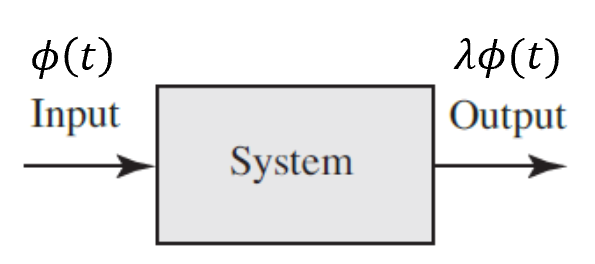

**ILL 1.1** *Eigenfunction of the system*

For a linear system, we can decompose an input signal $x\left(t\right)$ as a superposition of eigenfunctions $x\left(t\right)=x_1 \phi_1 \left(t\right)+x_2 \phi_2 \left(t\right)+\ldotp \ldotp \ldotp +x_n \phi_n \left(t\right)$, where $\left\lbrace \phi_1 \left(t\right),\phi_2 \left(t\right),\phi_3 \left(t\right),\ldotp \ldotp \ldotp ,\phi_n \left(t\right)\right\rbrace$are the eigenfunctions. If we also know the corresponding eigenvalues$\left\lbrace \lambda_1 ,\lambda_2 ,\ldotp \ldotp \ldotp ,\lambda_n \right\rbrace ,$ the output signal can be then expressed as: 


$$y\left(t\right)=\lambda_1 x_1 \phi_1 \left(t\right)+\lambda_2 x_2 \phi_2 \left(t\right)+\ldotp \ldotp \ldotp +\lambda_n x_n \phi_n \left(t\right)$$


or if the dimension of the eigenspace is infinite, the superposition can be expressed as $x\left(t\right)=\int X_{\omega \;} \phi {\;}_{\omega \;} \left(t\right)d\omega$. The form of the output signal is similar to the finite case and will be discussed towards the end of this lecture. 

### 1.1 Fourier transform

It can be proven that the eigenfunctions of a LSI system are exponential functions: $\phi_{\omega } \left(t\right)=\frac{1}{2\pi }e^{i\omega t}$, where 𝜔 is a real number. Here, we use imaginary exponential, so that the eigenfunctions are bounded.  The exponential functions can also be expressed in frequency $\xi$; $\omega =2\pi \xi$ is interpreted as the angular frequency. A signal $f\left(t\right)$ can be expressed as the superposition of the eigenfunctions.The coefficient $\frac{1}{2\pi \;}$is the result of normalization.


$$f\left(t\right)=\int F\left(\omega \right)\phi_{\omega } \left(t\right)d\omega =\frac{1}{2\pi }\int F\left(\omega \right)e^{i\omega t} d\omega$$


This expression is better known as the inverse Fourier transform (IFT). 

Since the eigenfunctions form an orthonormal basis, to calculate the coefficient $F\left(\omega \;\right)$, we just need to project the signal to the complex conjugate of the eigenfunctions. This process is called the Fourier transform:


$$F\left(\omega \right)=\int f\left(t\right)e^{-i\omega t} \textrm{dt}$$
	

### 1.2 Fourier series

When the signal$f\left(t\right)$ is periodic with period $T$, the frequency spectrum is discrete. The coefficient series $\left\lbrace c_k \right\rbrace$ is called the Fourier series of the periodic signal$f\left(t\right)$:


$$f\left(t\right)=\sum_{k=-\infty }^{\infty } c_k {\;e}^{\textrm{ik}\omega_0 \;t}$$


where $\omega_0$ is the fundamental frequency, $\omega_0 =\frac{2\pi }{T}$. Coefficient $c_k$ is calculated by the integral:


$$c_k =\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} f\left(x\right)e^{-\textrm{ik}\frac{2\pi }{T}t} \textrm{dt}$$


### 1.3 Discrete Fourier transform

For discrete signal frequency analysis, discrete Fourier transform (DFT) considers the signal to be discrete and periodic. One period has $N$ samples. The discrete Fourier basis are $\left\lbrace e^{i\frac{2\pi k}{N}n} \right\rbrace ,\;k=0,1,\ldotp \ldotp \ldotp ,N-1$. 

It can be observed that the base function is also perodic regarding to $k$. $e^{i\frac{2\pi \left(k+\textrm{mN}\right)}{N}n} =e^{i\frac{2\pi k}{N}n} e^{\textrm{i2}\pi \;\textrm{mn}} =e^{i\frac{2\pi k}{N}n}$. Therefore, the DFT spectrum is also perodic with a period of $N$ samples. We only need to calculate $N$ terms. The DFT of signal$f\left\lbrack n\right\rbrack$ is:


$$F\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} f\left\lbrack n\right\rbrack e^{-i\frac{2\pi k}{N}n} ,\;\;\;\;\;\;\;k=0,1,\ldotp \ldotp \ldotp ,N-1$$


and the inverse DFT is:


$$f\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} F\left\lbrack k\right\rbrack e^{\left(j\frac{2\pi \textrm{kn}}{N}\right)} ,\;\;\;\;\;n=0,1,\ldotp \ldotp \ldotp ,N-1$$


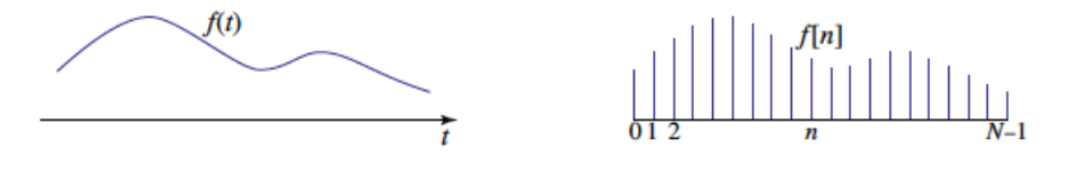

**ILL. 1.2** *Continous signal vs periodic discrete signal for discrete Fourier transform.*

When $N=2^p ,p=1,2,3,\ldotp \ldotp \ldotp$ fast Fourier transform (FFT) algorithm can be used to accelerate the DFT computation. The MATLAB function to perform FFT is `fft()`. Notice that in the time and frequency domain, the series is not centered at 0. Since the series are periodic, the terms with indices between $\frac{N}{2}$ and $N-1$ is the same as those between $-\frac{N}{2}$ and $-1$, i.e., $f\left\lbrack -n\right\rbrack =f\left\lbrack N-n\right\rbrack ,n=-1,-2,\ldotp \ldotp \ldotp ,-\frac{N}{2}$. In MATLAB, `fftshift()` can be used to center the $k=0$ freqeuncy component of the series. 

In essense, Fourier transform, Fourier series and DFT are all used to calculate the coefficient of a signal expanded on LSI eigenbasis, depending on the perodicity and continuity of the signal. The transforms and their corresponding signal types are summarized in Table 1.1.

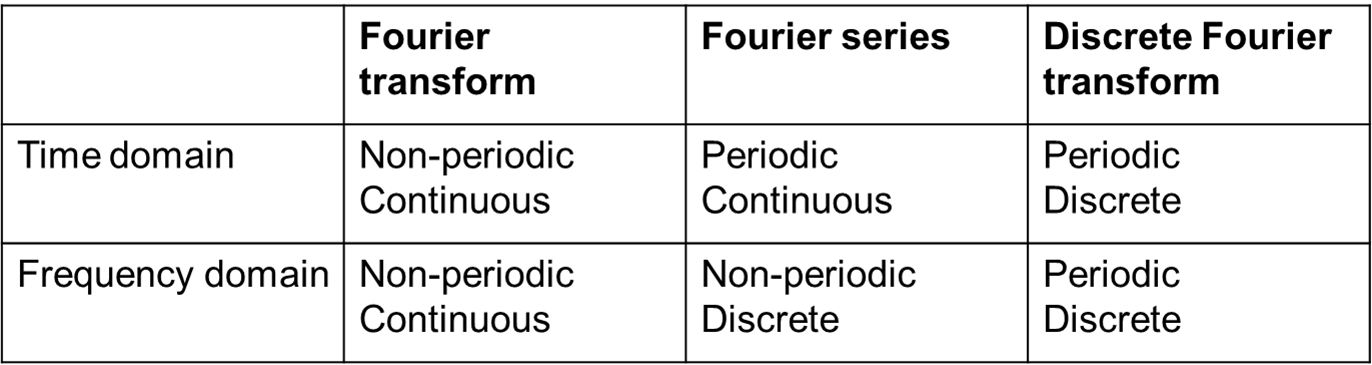

**Table 1.1** Fourier transform, Fourier series, and discrete Fourier transform

***Example 1.1 ***

Display the phase and amplitude of discrete Fourier transform results.

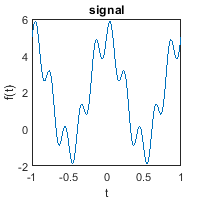

% The Fourier base is usually complex valued, the Fourier coefficient therefore has
% real and imaginary parts. To plot the frequency components, we need both
% the amplitude and phase plots.

n=4096;
t=linspace(-1,1,n); % unit in sec
dt = t(2)-t(1);
f=2+3.*cos(2*1*pi.*t)+1.*sin(2*5*pi.*t); % ths signal f
figure;
plot(t,f);
title('signal');
xlabel('t');ylabel('f(t)');
set(gcf,'Position',[100 100 200 200]);

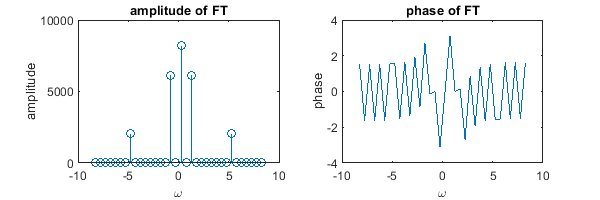

% frequency analysis with DC term centered using fftshift()
f_hat=fftshift(fft(fftshift(f))); 

omega=linspace(-(1/2./dt),(1/2./dt),n); %frequency axis, unit in 2pi*Hz
figure;
subplot(121);
stem(omega(2032:2065),abs(f_hat(2032:2065)));
title('amplitude of FT');
xlabel('\omega');ylabel('amplitude');
subplot(122);
plot(omega(2032:2065),angle(f_hat(2032:2065)));
title('phase of FT');
xlabel('\omega');ylabel('phase');
set(gcf,'Position',[100 100 600 200]);

***Example 1.2 ***

Discrete Fourier transform of a constant signal.


$$f\left\lbrack n\right\rbrack =1\overset{\textrm{DFT}}{\longrightarrow} F\left\lbrack k\right\rbrack =2\pi \delta \left\lbrack k\right\rbrack$$


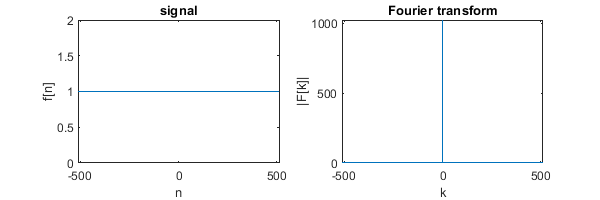

n=1024;
f=ones(1,n);
f_hat=fftshift(fft(fftshift(f)));
figure;
subplot(121);
plot(-n/2:n/2-1,fftshift(f));
title('signal');
xlabel('n');ylabel('f[n]');
subplot(122)
plot(-n/2:n/2-1,f_hat);
title('Fourier transform');
xlabel('k');ylabel('|F[k]|');
set(gcf,'Position',[100 100 600 200]);

***Example 1.3 ***

Discrete Fourier transform of an impulse (unit sample function).


$$f\left\lbrack n\right\rbrack =\delta \left\lbrack k\right\rbrack \overset{\textrm{DFT}}{\longrightarrow} F\left\lbrack k\right\rbrack =1$$


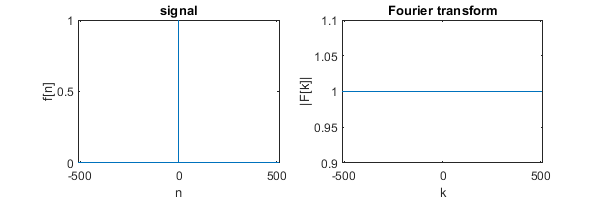

n=1024;
f=zeros(1,n);
f(1)=1;
f_hat=fftshift(fft(fftshift(f)));
figure;
subplot(121);
plot(-n/2:n/2-1,fftshift(f));
title('signal');
xlabel('n');ylabel('f[n]');
subplot(122);
plot(-n/2:n/2-1,abs(f_hat));
title('Fourier transform');
xlabel('k');ylabel('|F[k]|');
ylim([0.9,1.1]);
set(gcf,'Position',[100 100 600 200]);

***Example 1.4. ***

Fourier transform of a rectangular function.


$$f\left(t\right)=\textrm{rect}\left(t\right)\overset{\textrm{FT}}{\longrightarrow} F\left(\omega \right)=\textrm{sinc}\left(\frac{\omega }{2\pi }\right)$$


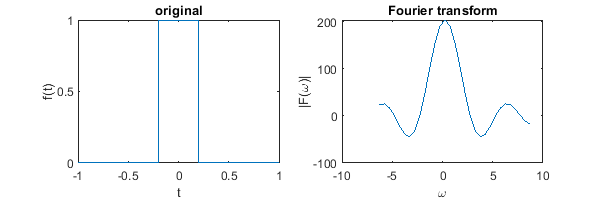

n=1024;
t=linspace(-1,1,n);
dt=t(2)-t(1); % time stepsize
f=zeros(1,n);
omega=linspace(-(1/2./dt),(1/2./dt),n);
f(abs(t)<.2)=1;
f_hat=fftshift(fft(fftshift(f)));
figure;
subplot(121);
plot(t,f);
title('original');
xlabel('t');ylabel('f(t)');
subplot(122);
plot(omega(500:530),real(f_hat(500:530)));
title('Fourier transform');
xlabel('\omega');ylabel('|F(\omega)|');
set(gcf,'Position',[100 100 600 200]);

***Example 1.5***

Fourier transform of a Gaussian function.


$$f\left(t\right)=e^{-\pi t^2 } \overset{\textrm{FT}}{\longrightarrow} F\left(\omega \right)=ce^{-\frac{\omega^2 }{4\pi }}$$


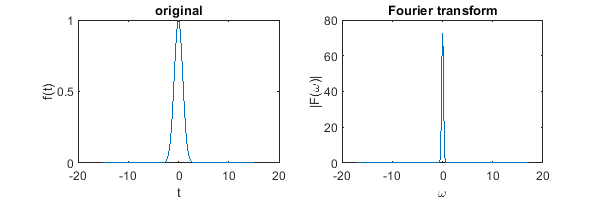

n=1024;
t=linspace(-15,15,n);
sigma = 1.5;
dt=t(2)-t(1);
f=exp(-pi.*t.^2/(2*sigma.^2));
omega=linspace(-(1/2./dt),(1/2./dt),n);
f_hat=fftshift(fft(fftshift(f)));
figure;
subplot(121);
plot(t,f);
title('original');
xlabel('t');ylabel('f(t)');
subplot(122);
plot(omega,abs(f_hat));
title('Fourier transform');
xlabel('\omega');ylabel('|F(\omega)|');
set(gcf,'Position',[100 100 600 200]);

Since a Guassian function's Fourier transform is still Gaussian, by definition, Gaussian functions are the eigenfunctions of Fourier transform! Though we have not show that Fourier transform is linear, you might already have suspected it. This important property makes Gaussian functions a popular choice for the discussion of linear systems.

***Example 1.6 ***

Fourier transform of pulse train.


$$f\left(t\right)=\sum \delta \left(t-\textrm{nT}\right)\overset{\textrm{FS}}{\longrightarrow} F\left(\omega \right)=\frac{1}{T}\sum \delta \left(\omega \;-k\frac{2\pi }{T}\right)$$


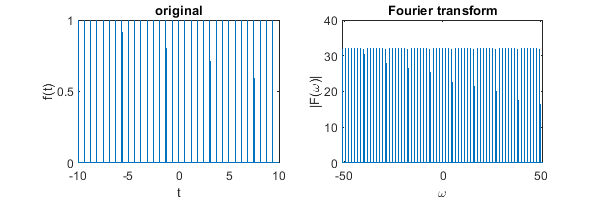

n=2048;
t=linspace(-10,10,n);
dt=t(2)-t(1);
omega=linspace(-(1/2./dt),(1/2./dt),n);
f=zeros(1,n);
dn = 64;% interval of the pulses
f(1:dn:end)=1;
f_hat=fftshift(fft(fftshift(f)));
figure;
subplot(121);
plot(t,f);
title('original');
xlabel('t');ylabel('f(t)');
subplot(122);
plot(omega,abs(f_hat));
title('Fourier transform');
xlabel('\omega');ylabel('|F(\omega)|');
set(gcf,'Position',[100 100 600 200]);

ILL. 1.2 summarize the results of the Fourier transform of some of the special functions shown in the examples above.

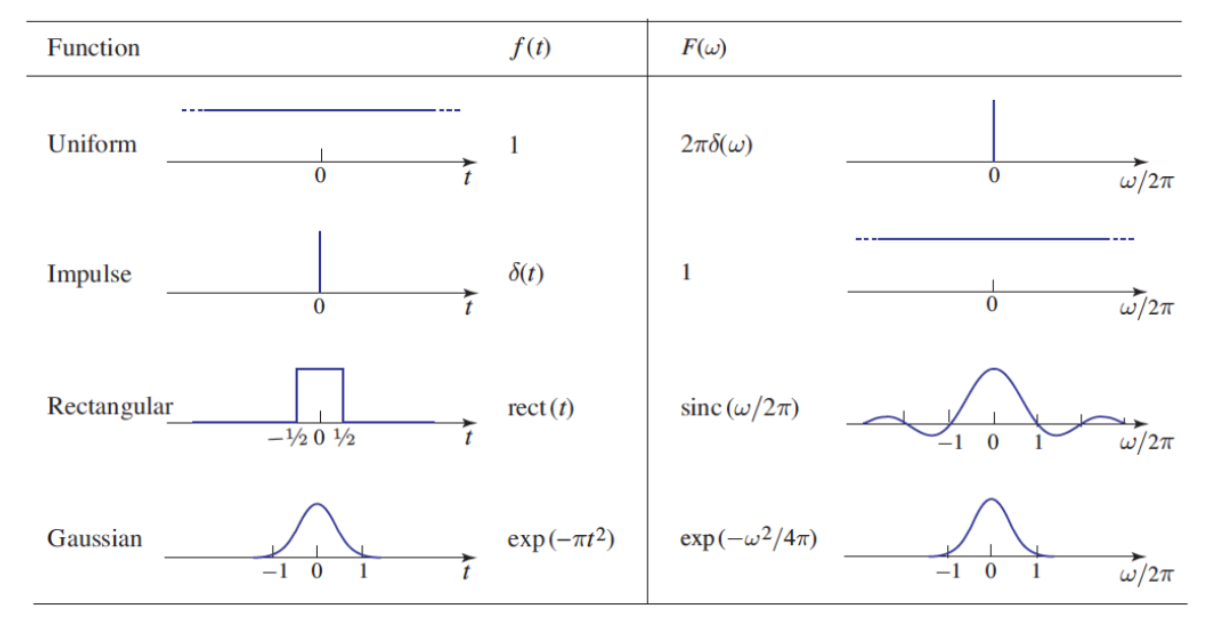

**ILL. 1.2 ***Summary of the Example 1.2-1.5* 

## 2. Fourier transform properties

Fourier transform properties include linearity, scaling, time translation, frequency translation, and convolution.

### 2.1 Linearity

The Fourier transform of the sum of two signals $f_{1\;} \left(t\right),f_2 \left(t\right)$ is the sum of their Fourier transforms$F_1 \left(\omega \right),F_2 \left(\omega \right)$.


$$f_1 \left(t\right)+f_2 \left(t\right)\overset{\textrm{FT}}{\longrightarrow} F_1 \left(\omega \right)+F_2 \left(\omega \right)$$


***Example 2.1 ***

Linearity

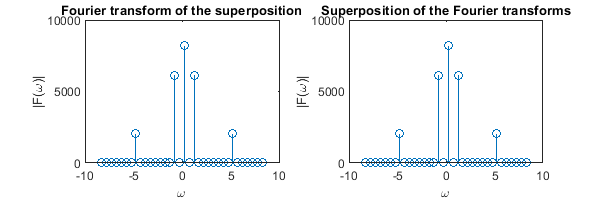

n= 4096;
t=linspace(-1,1,n); 
dt = t(2)-t(1);
omega=linspace(-(1/2./dt),(1/2./dt),n);
f1=1+3.*cos(2*1*pi.*t);
f2=1+1.*sin(2*5*pi.*t);

f1_hat=fftshift(fft(fftshift(f1)));
f2_hat=fftshift(fft(fftshift(f2)));
f_hat = fftshift(fft(fftshift(f1+f2)));
figure;
subplot(121);
stem(omega(2032:2065),abs(f_hat(2032:2065)))
title('Fourier transform of the superposition');
xlabel('\omega');ylabel('|F(\omega)|');
subplot(122);
stem(omega(2032:2065),abs(f1_hat(2032:2065)+f2_hat(2032:2065)));
title('Superposition of the Fourier transforms');
xlabel('\omega');ylabel('|F(\omega)|');
set(gcf,'Position',[100 100 600 200]);

### 2.2 Scaling

If $f\left(t\right)$ has a Fourier transform $F\left(\omega \right)$ and $\tau$ is a real scaling factor, then $f\left(\frac{t}{\tau }\right)$ has a Fourier transform $\left|\tau \right|F\left(\tau \omega \right)$. This means that if $f\left(t\right)$ is scaled by a factor $\tau$, its Fourier transform is scaled by a factor $\frac{1}{\tau }$ in time. 

For example, if $\tau >1$, then $f\left(\frac{t}{\tau }\right)$is a streched version of $f\left(t\right)$, whereas $F\left(\tau \omega \right)$ is a srunken version of $F\left(\omega \right)$. Also, the Fourier transform of $f\left(-t\right)$ is $F\left(-\omega \right)$.

***Example 2.2 ***

Scaling

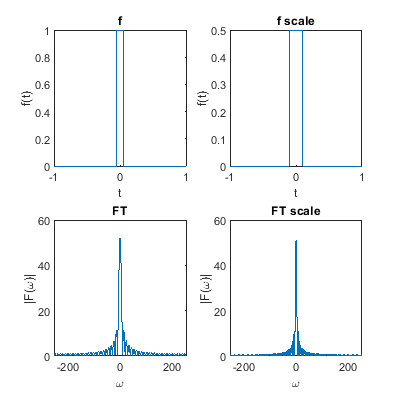

n=1024;
t=linspace(-1,1,n);
dt=t(2)-t(1);

f=zeros(1,n);
f_s=zeros(1,n);
omega=linspace(-(1/2./dt),(1/2./dt),n);
f(abs(t)<0.05)=1;
f_s(abs(t)<0.1)=1/2;
f_hat=fftshift(fft(fftshift(f)));
f_s_hat=fftshift(fft(fftshift(f_s)));

figure;
subplot(221);
plot(t,f);
title('f');
xlabel('t');ylabel('f(t)');
subplot(222);
plot(t,f_s);
title('f scale');
xlabel('t');ylabel('f(t)');
subplot(223);
plot(omega,abs(f_hat));
title('FT');
xlabel('\omega');ylabel('|F(\omega)|');
subplot(224);
plot(omega,abs(f_s_hat));
title('FT scale');
xlabel('\omega');ylabel('|F(\omega)|');
set(gcf,'Position',[100 100 400 400]);

### 2.3 Time translation

If $f\left(t\right)$ has a Fourier transform $F\left(\omega \right)$, the Fourier transform of $f\left(t-\tau \right)$ is $e^{-j\omega \tau \;} F\left(\omega \right)$. Thus, delay by time $\tau$ is equivalent to multiplying the Fourier transform by a phase factor $e^{-j\omega \tau }$.

***Example 2.3***

Time translation

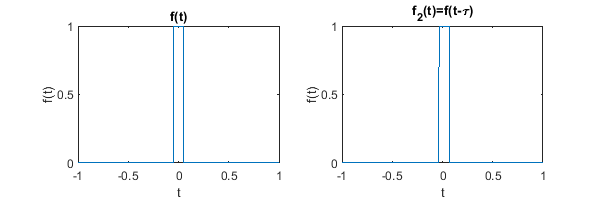

n=1024;
t=linspace(-1,1,n);
dt=t(2)-t(1);
omega=linspace(-(1/2./dt),(1/2./dt),n);
f=zeros(1,n);
f_f=zeros(1,n);
wt = 0.05;
f(abs(t)<wt)=1; % rectangular function with width wt
tau = 8*dt; % time shift
f_f(abs(t-tau)<wt)=1;

figure;
subplot(121);
plot(t,f);
title('f(t)');
xlabel('t');ylabel('f(t)');
subplot(122);
plot(t,f_f);
title('f_2(t)=f(t-\tau)');
xlabel('t');ylabel('f(t)');
set(gcf,'Position',[100 100 600 200]);

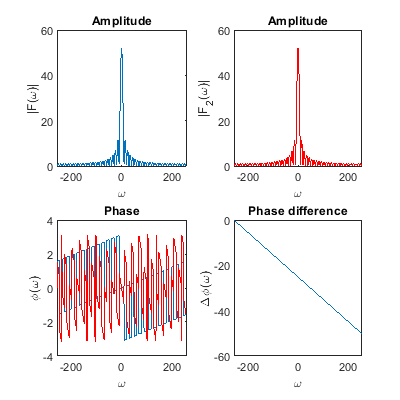

f_hat=fftshift(fft(fftshift(f)));
f_f_hat=fftshift(fft(fftshift(f_f)));

figure;
subplot(221);
plot(omega,abs(f_hat));
title('Amplitude');
xlabel('\omega');ylabel('|F(\omega)|');
subplot(222);
plot(omega,abs(f_f_hat),'r');
title('Amplitude');
xlabel('\omega');ylabel('|F_2(\omega)|');
subplot(223);
plot(omega,angle(f_hat));
title('Phase')
xlabel('\omega');ylabel('\phi(\omega)');
hold on;
plot(omega,angle(f_f_hat),'r');
hold off;
subplot(224);
plot(omega,unwrap(angle(f_f_hat)-angle(f_hat)));
title('Phase difference');
xlabel('\omega');ylabel('\Delta\phi(\omega)');
set(gcf,'Position',[100 100 400 400]);

### 2.4 Frequency translation

If $F\left(\omega \right)$ is the Fourier transform of $f\left(t\right)$, the Fourier transform of $f\left(t\right)e^{j\omega_0 t}$is $F\left(\omega -\omega_0 \right)$. Thus, multiplication by a harmonic function of frequency $\omega_0$ is equivalent to shifting the Fourier transform to a higher frequency $\omega_0$.This is the frequency domain equivalent of the time translation.

### 2.5 Convolution

If the Fourier transforms of $f_1 \left(t\right)$and $f_2 \left(t\right)$ are $F_1 \left(\omega \right)$ and $F_2 \left(\omega \right)$, respectively, then the inverse Fourier transform of the product is the convolution of $f_1 \left(t\right)$ with $f_2 \left(t\right)$.


$$f\left(t\right)=\int_{-\infty }^{\infty } f_1 \left(\tau \;\right)f_2 \left(t-\tau \right)d\tau$$



$$F\left(\omega \right)=F_1 \left(\omega \right)F_2 \left(\omega \right)$$


The convolution in the time domain is equivalent to multiplication in the frequency domain.

***Example 2.4 ***

Convolution in time domain is equivalent to multiplication in Fourier domain

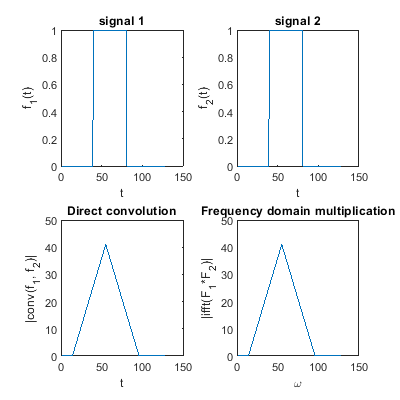

f1=zeros(1,128);
wn = 40:80; % width of rectangular function
f1(wn)=1; % step function
f2=zeros(1,128);
f2(wn)=1; % step function
f_c=conv(f1,f2,'same'); % convolution
% multiplication in frequency domain
f_f=fftshift(ifft(fft(fftshift(f1)).*fft(fftshift(f2))));

figure;
subplot(221);
plot(f1);
title('signal 1');
xlabel('t');ylabel('f_1(t)');
subplot(222);
plot(f2);
title('signal 2');
xlabel('t');ylabel('f_2(t)');
subplot(223);
plot(abs(f_c));
title('Direct convolution');
xlabel('t');ylabel('|conv(f_1, f_2)|');
subplot(224);
plot(abs(f_f));
title('Frequency domain multiplication');
xlabel('\omega');ylabel('|ifft(F_1*F_2)|');
set(gcf,'Position',[100 100 400 400]);

## **3. Nyquist sampling**

Assuming that $f\left(t\right)$ is a continuous signal, its sampled version $f_s \left(t\right)$ can be expressed as a product with a delta pulse train:


$$\hat{f} \left(t\right)=f\left(t\right)\sum_{n=-\infty }^{\infty } \delta \left(t-\textrm{nT}\right)$$


Where T is the sampling period, $f_s$=$\frac{1}{T}$ is the sampling frequency ($\textrm{Hz}$), and $\omega_s =2\pi f_s =\frac{2\pi }{T}$ is the sampling frequency with a unit of $\frac{\textrm{rad}}{\sec }$.

Therefore, by considering the Fourier convolution theorem: if in time domain $g\left(t\right)=g_1 \left(t\right)\;g_2 \left(t\right)$, then in freqeuncy domain $G\left(\omega \right)=\int_{-\infty }^{\infty } G_1 \left(\omega^{\prime } \right)G_2 \left(\omega -\omega^{\prime } \right)d\omega^{\prime }$, we multiply $f\left(t\right)$ in the impulse train $\sum_{n=-\infty }^{\infty } \delta \left(t-\textrm{nT}\right)$ which is a periodic function. Thus the Fourier series of the multiplication will be:


$$\begin{array}{l}
f\left(t\right)\overset{\textrm{FT}}{\longrightarrow} F\left(\omega \;\right)\\
\sum \delta \left(t-\textrm{nT}\right)\overset{\textrm{FT}}{\longrightarrow} \frac{1}{T}\sum \delta \left(\omega \;-k\omega_s \right)
\end{array}$$


And then the Fourier transform of the sampled signal $\hat{f} \left(t\right)$ is:


$$\hat{F} \left(\omega \right)=\frac{1}{T}\sum_{n=-\infty }^{\infty } \int \delta \left(\omega^{\prime } \;-k\omega_s \right)F\left(\omega -\omega^{\prime } \right)d\omega^{\prime } \;=\frac{1}{T}\sum_{n=-\infty }^{\infty } F\left(\omega -k\omega_s \right),$$


which is the superposition of the shifted spectrum with a spacing of $\omega_s =2\pi /T$.

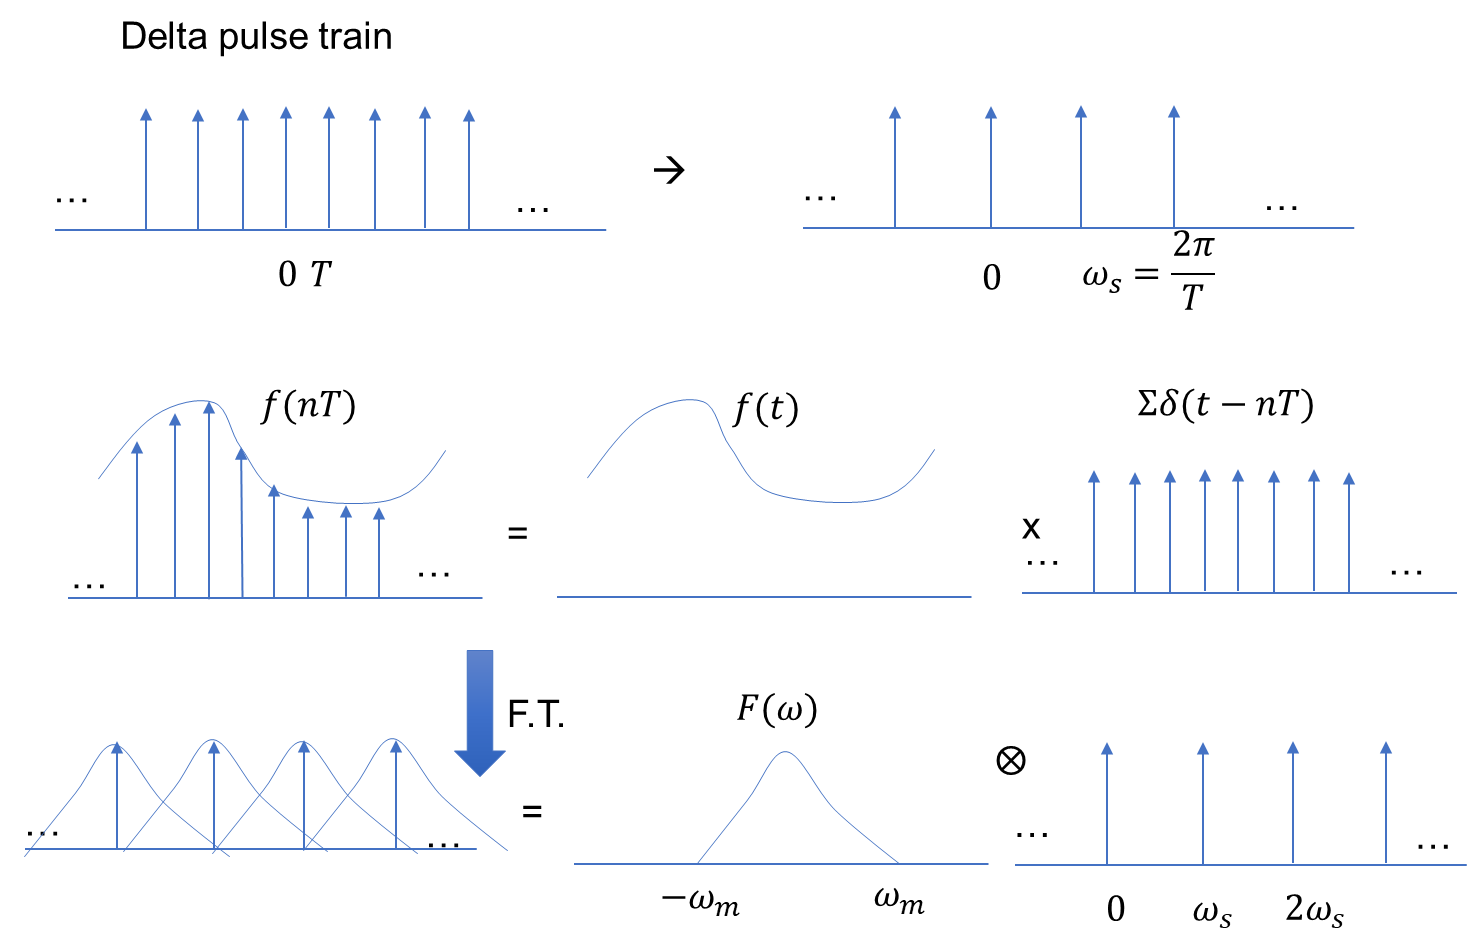

**ILL. 3.1*** Frequency spectrum of a sampled signal.*

The sampling frequency should be at least twice the highest frequency contained in the signal.

Nyquist sampling theorem: $\omega_s >2\omega_m$

***Example 3.1***

Aliasing

When the sampling frequency is lower than the Nyquist freqeuncy, $\omega_s <2\omega_m$, the frequecy will 'alias' into the neighboring intervals. This aliased freqeuncy components will cause confusion with the original freqeuncy components. One common phenomena you may have observed on TV is that the car's wheel seems to be spinning backwards slowly, while the car is clearly moving forward. This is because the wheel rotation freqeuncy is higher than the camera frame rate (or your TV refresh rate). The wheel rotation frequency is aliased to the low frequency range (can also be negative), and you observe a back spinning wheel. ILL. 3.1 illustrates the aliasing in the freqeuncy domain.

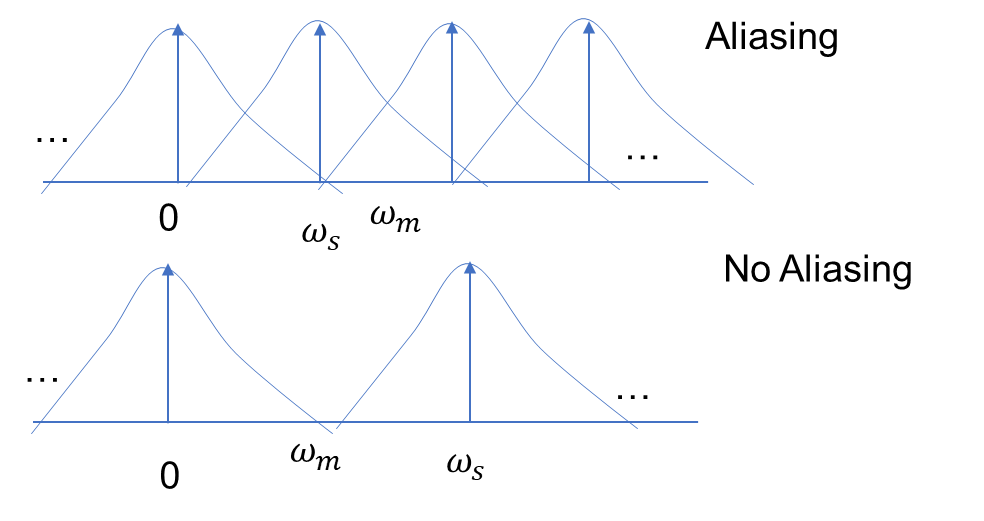

**ILL. 3.1*** Aliasing in spectral domain*

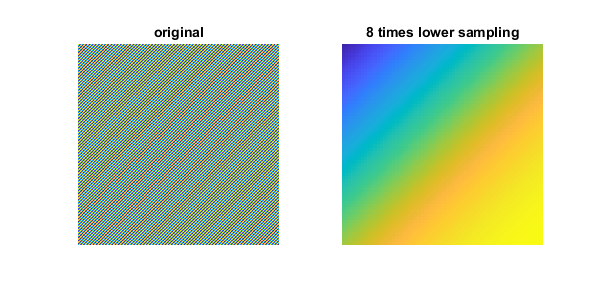

x=linspace(-4,4,512);
y=linspace(-4,4,512);
[X,Y]=ndgrid(x,y);

Img=1+sin(16*pi.*X+16*pi.*Y); % image containing high frequency signal
figure;
subplot(121);
imagesc(Img);
axis image;axis equal;axis off;
title('original')

m =8; % sampling interval
Img_ls=Img(1:m:end,1:m:end); % the aliased signal
subplot(122);
imagesc(Img_ls);
title([num2str(m),' times lower sampling']);
axis image;axis equal;axis off;
set(gcf,'Position',[100 100 600 300]);

Please try to adjust the down sampling m to 8. What do you observe? Can you explain what you see? 

## **4. 2D Fourier transform**

An image can be decomposed into 2D exponential functions:


$$f\left(x,y\right)=\frac{1}{4\pi^2 }\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } F\left(k_x {,k}_y \right)e^{-j\left(k_x x+k_y y\right)} dk_x dk_y$$



$$F\left(k_x ,k_y \right)=\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } f\left(x,y\right)e^{j\left(k_x x+k_y y\right)} \textrm{dx}\textrm{dy}$$


***Example 4.1 ***

2D fast Fourier transform of a 2D harmonic signal.

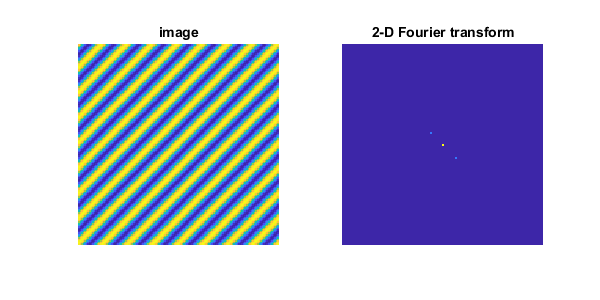

n=128;
a=2*pi/8;
x=(-n/2+1):n/2;
y=(-n/2+1):n/2;
[X,Y]=meshgrid(x,y);
Img = 2+cos(a/2.*X+a/2.*Y);
Img_hat=fftshift(fft2(Img));
figure;
subplot(121);
imagesc(Img);
axis image;axis off;axis equal;
title('image');
subplot(122);
imagesc(abs(Img_hat));
axis image;axis off;axis equal;
title('2-D Fourier transform');
set(gcf,'Position',[100 100 600 300]);

***Example 4.2 ***

2D fast Fourier transform of square (2D rect function).

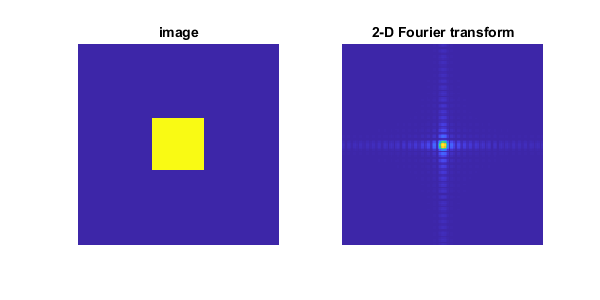

n=128;
Img=zeros(n);
Img((3*n/8):(5*n/8),(3*n/8):(5*n/8))=1; % square with side length of n/4.
Img_hat=fftshift(fft2(Img));
figure;
subplot(121)
imagesc(Img)
axis image;axis off;axis equal;
title('image');
subplot(122)
imagesc(abs(Img_hat))
axis image;axis off;axis equal;
title('2-D Fourier transform');
set(gcf,'Position',[100 100 600 300]);

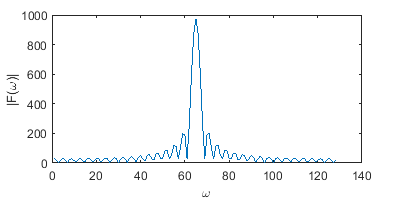

figure;
plot(abs(Img_hat(64,:)));
xlabel('\omega');ylabel('|F(\omega)|');
set(gcf,'Position',[100 100 400 200]);

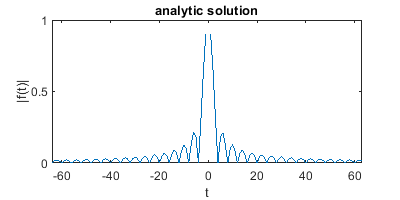

figure;
t=linspace(-n/2,n/2-1,n);
y=sin(pi/4*t)./(pi/4*t);
plot(t,abs(y));
xlabel('t');ylabel('|f(t)|')
title('analytic result')
set(gcf,'Position',[100 100 400 200]);

***Example 4.3 ***

2D fast Fourier transform of circle. 

The Fourier transform of a circular function is Sombrero function, the ideal Airy pattern for a far-field diffraction pattern of a circular aperture. 

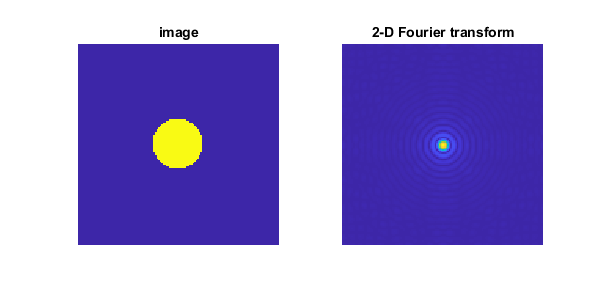

n=128;
x=(-n/2+1):n/2;
y=(-n/2+1):n/2;
[X,Y]=ndgrid(x,y);
Img=zeros(n);
Img(X.^2+Y.^2<(n/8)^2)=1;% circile with radius n/8
Img_hat=fftshift(fft2(Img));
figure;
subplot(121);
imagesc(Img);
axis image;axis off;axis equal;
title('image');
subplot(122);
imagesc(abs(Img_hat));
axis image;axis off;axis equal;
title('2-D Fourier transform');
set(gcf,'Position',[100 100 600 300]);

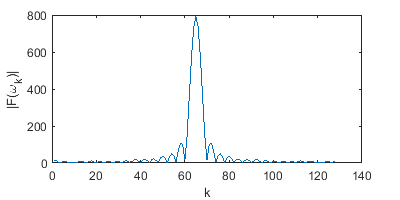

figure;
plot(abs(Img_hat(n/2+1,:)));
xlabel('k');ylabel('|F(\omega_k)|');
set(gcf,'Position',[100 100 400 200]);

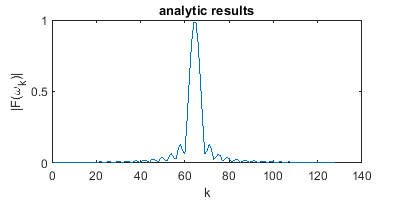

% compare with sombrero function.
rho_a=(1/8);% radius
rho=linspace(-1,1,n)./rho_a;
h=2*besselj(1,2*pi.*rho)./(2*pi.*rho);
figure;
plot(abs(h));
xlabel('k');ylabel('|F(\omega_k)|');
title('analytic results')
set(gcf,'Position',[100 100 400 200]);

***Example 4.4 ***

2-D fast Fourier transform of an image

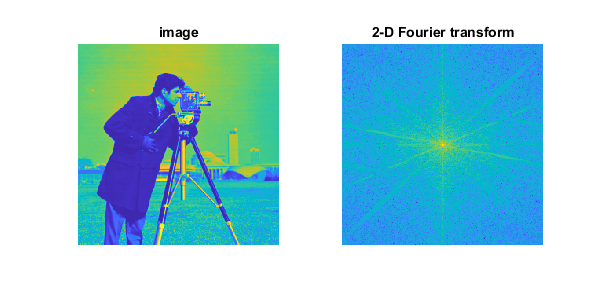

Img=imread('cameraman.tif');
Img_hat=fftshift(fft2(Img));
figure;
subplot(121);
imagesc(Img);
axis image;axis off;axis equal;
title('image');
subplot(122);
imagesc(log(abs(Img_hat)));
axis image;axis off;axis equal;
title('2-D Fourier transform');
set(gcf,'Position',[0 100 600 300]);